# **Notas para o teste 2**

## Espetrograma

Uma sequência de tons diferentes tem um espetro idêntico ao dos mesmos tons considerados em simultâneo:

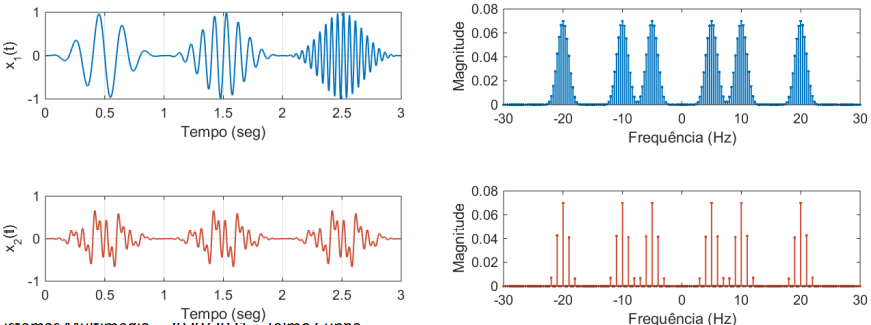

Nestes casos, é usual considerar-se a short-time FFT, cujo resultado é conhecido por Espetrograma.

spectrogram('…');

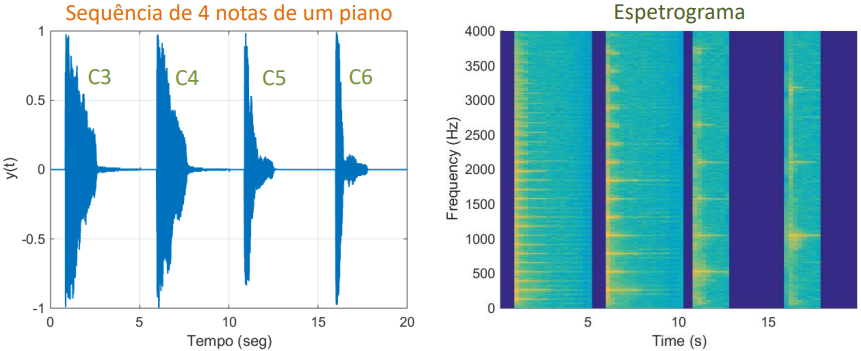

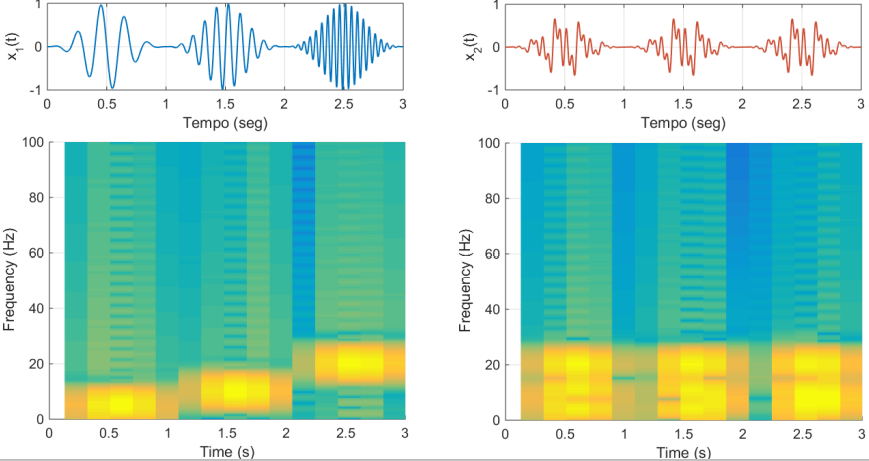

## **Amostragem de sinais**

O tratamento e análise de sinais com recurso a processadores digitais é efetuado no domínio de tempo discreto. Tal requer, naturalmente, que os sinais que evoluem continuamente ao longo do tempo sejam amostrados.

O processo de amostragem consiste em adquirir amostras do sinal (tipicamente a um ritmo periódico).

Para não perder informação, a frequência de amostragem tem de ser superior ao dobro da frequência mais elevada do sinal (**Critério de Nyquist**).

### Reconstrução de sinais amostrados

A reconstrução ideal deve considerar a função seno cardinal em vez de pulsos retangulares.

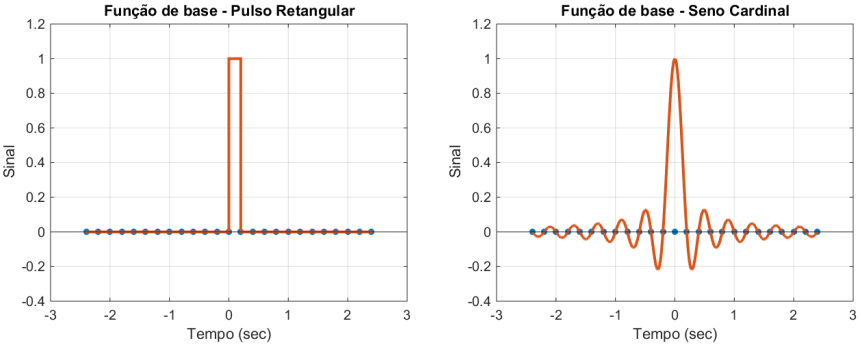


$$h\left(t\right)=\frac{\sin \left(\pi f_a t\right)}{\pi f_a t}$$


### Aliasing

Por vezes a reconstrução leva a frequências superiores a $\frac{f_a }{2}$. Por isso, o processo de amostragem deve ser precedido de um filtro *anti-aliasing*. 

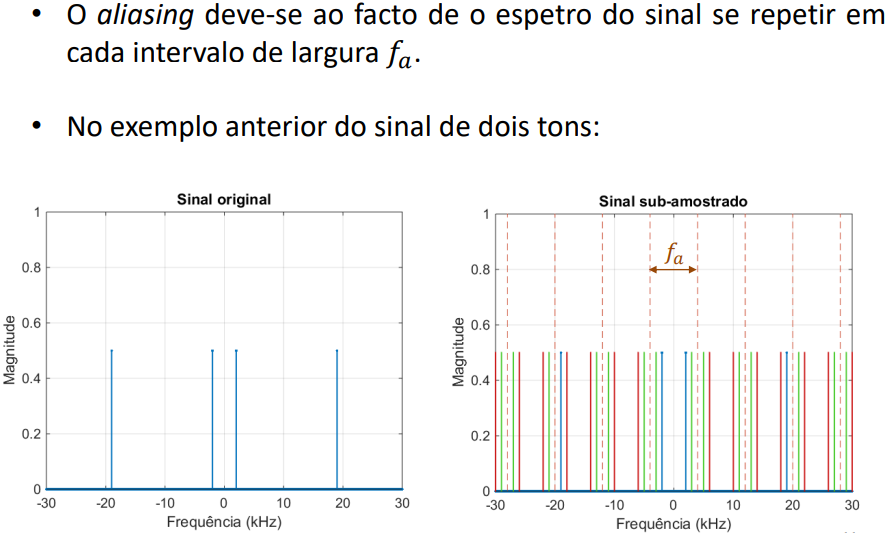

### Quantização da amplitude dos sinais

A amplitude dos sinais é discreta nos sistemas de aquisição de sinais. Cada amostra é armazenada num número limite de bits.

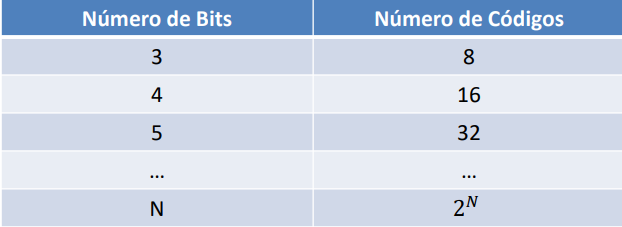

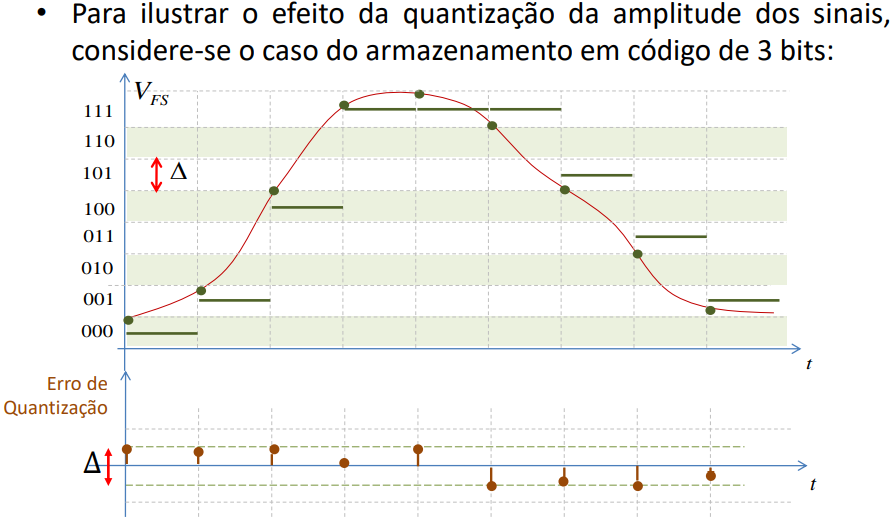

Intervalo de amplitude: $\Delta =\frac{V_{\mathrm{FS}} }{2^N }$

Potência do erro de quantização: $P\left(\epsilon \right)=\frac{\Delta^2 }{12}$

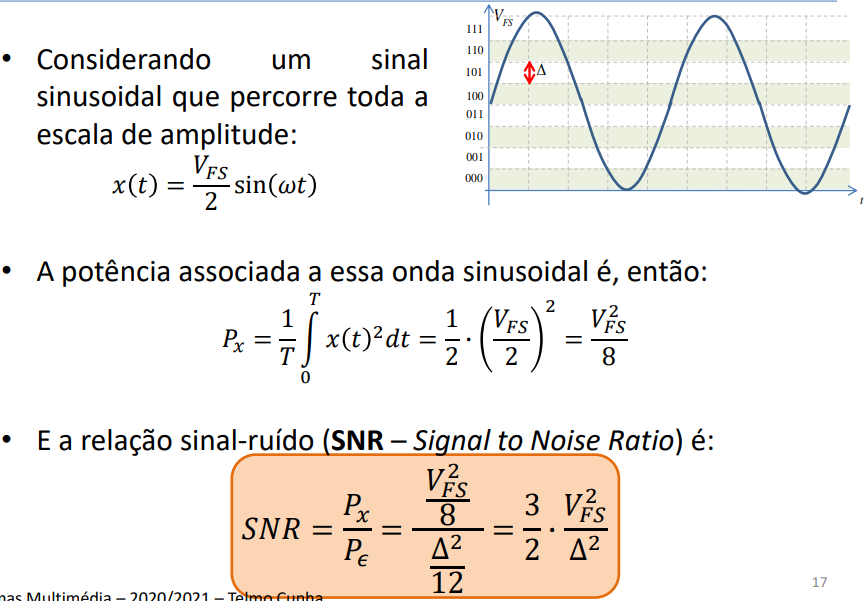

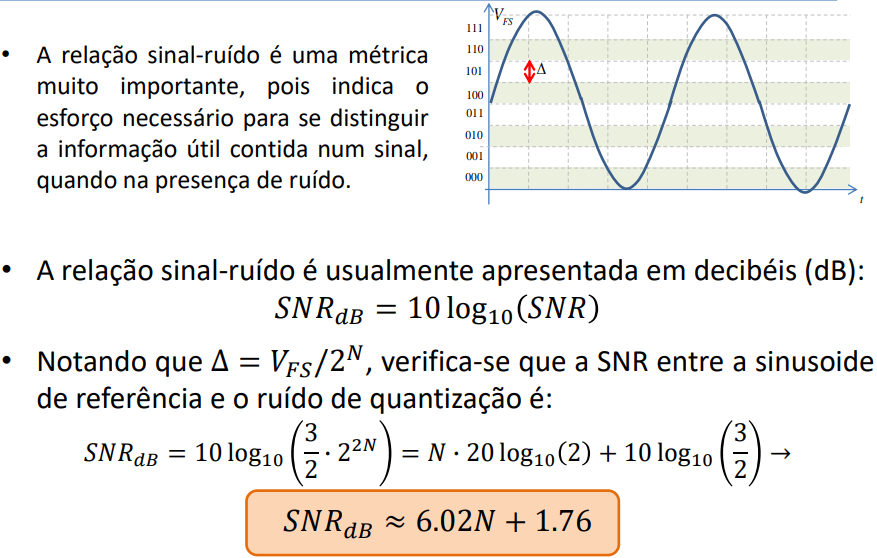

Exemplo - Quantização de seno em 3 bits:

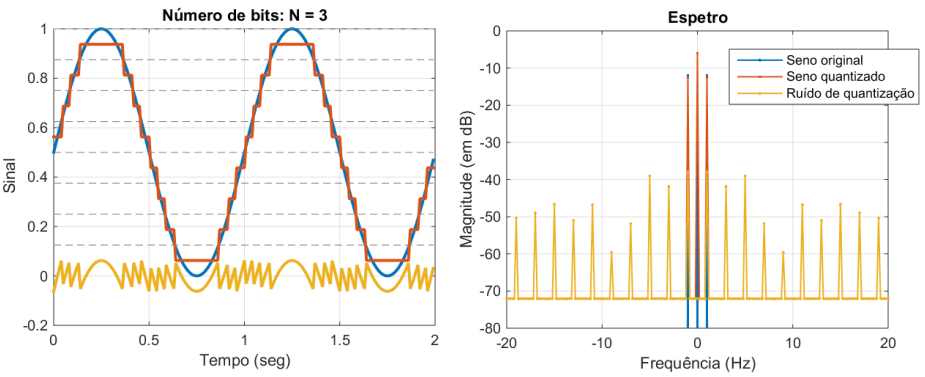

### Número de bits efetivos (ENOB)

Sendo verificada uma determinada relação sinal-ruído, qual é o número de bits que se obtém na representação da informação útil?


$$\mathrm{ENOB}\approx \frac{{\mathrm{SNR}}_{\mathrm{dB}} -1\ldotp 76}{6\ldotp 02}$$


Exemplo da quantização (4 bits) de um sinal com ruído:

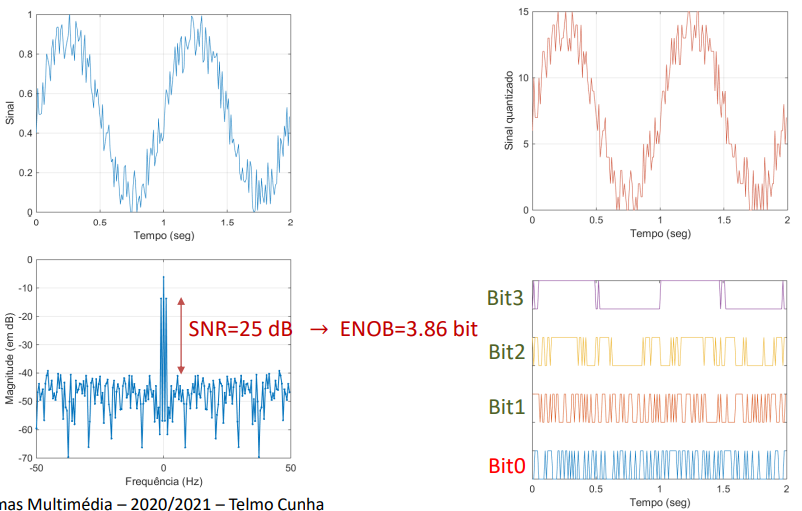

## Funções

Ler e reproduzir som:

load("Guitar03.mat")
sound(x,fa);

Gerar sinal com ruído:

function [x,t] = GeraSinal(N,Ta)
% Distribuição normal. normrnd(média,desvio,número-de-pontos)
phi = normrnd(0,pi,[1,N]);
phi_i1 = zeros(1,N);
for n = 2:N
    phi_i1(n) = phi_i1(n-1) + (phi(n)+phi(n-1))*Ta/2;
end

phi = normrnd(0,pi,[1,N]);
phi_i2 = zeros(1,N);
for n = 2:N
    phi_i2(n) = phi_i2(n-1) + (phi(n)+phi(n-1))*Ta/2;
end

t = (0:N-1)*Ta;
% Aterar x para corresponder ao sinal + ruído!
x = sin(2*pi*t) + ... % Sinal
    0.5*sin(2*pi*10*t + 10*phi_i1) + 0.5*sin(2*pi*12*t + 10*phi_i2); % Ruído
end

Espetro:

[X,f] = espetro(x,Ta);
Fa = 1/Ta;
plot(f,abs(X))
xlim([-Fa/2,Fa/2])
xlabel('Frequência (Hz)')
ylabel('Amplitude')
title('Amplitude em função da frequência')
grid

function [X,f] = espetro(x,Ta)
% X é vetor da mesma dimensão de x, com coeficientes da DFT de x(t)
% f é vetor da mesma dimensão de x, com as frequências de cada componente de X
N = length(x);
Fa = 1/Ta;

f = (0:N-1)*Fa/N - Fa/2; % ou f = -Fa/2:Fa/N:Fa/2
X = fftshift(fft(x))/N;
end

Aplicar filtro entre $\left\lbrack -2,0\right\rbrack \cup \left\lbrack 0,2\right\rbrack$ Hz e reconstruir do sinal:

fmin = 0;
fmax = 2;

filtro = zeros(1,length(f)); % Inicializar a zeros
filtro(f>fmin & f<fmax) = 1;
filtro(f>-fmax & f<-fmin) = 1;
filtro = logical(filtro); % Transformar numa variável True/False

figure(3)
plot(f,filtro)
title('Filtro')
xlim([-50,50])
ylim([0,1.5])

j = 0;
x_filt = X(filtro);
new_x = zeros(length(X),1);
for i = 1:length(filtro)
    if filtro(i) == 1
        j = j + 1;
        new_x(i) = x_filt(j);
    end
end

w = reconstroi(new_x);
figure(1)
hold on
plot(t,w,'r-')
legend('Sinal original','Sinal filtrado')

function x = reconstroi(X)
N = length(X);
x = ifft(fftshift(X))*N;
end